# Sample script of scaledActivationLayer

 Copyright (c) Shogo MURAMATSU, 2021

 All rights reserved.


type scaledActivationLayer

classdef scaledActivationLayer < nnet.layer.Layer
    % SUBBANDACTIVATIONLAYER
    %
    % SSCB -> SSCB
    % 
    % Copyright (c) Shogo MURAMATSU, 2021
    % All rights reserved.
    % 
    
    properties
        NumberOfChannels
        ActivationFunction
    end
    
    properties(Learnable)
        % Layer learnable parameters
        ScaleIn
        BiasIn
        ScaleOut
        BiasOut
    end
    
    methods
        function layer = scaledActivationLayer(varargin) 
            p = inputParser;
            addParameter(p,'Name','')
            addParameter(p,'ScaleIn',1)
            addParameter(p,'BiasIn',0)
            addParameter(p,'ScaleOut',1)
            addParameter(p,'BiasOut',0)
            addParameter(p,'NumberOfChannels',1)
            addParameter(p,'ActivationFunction','None')
            parse(p,varargin{:})
            
            % Set layer name.
            layer.Name = p.Results.Name;
            layer.NumberOfChannels = p.Results.NumberOfChannels;
    

layer = scaledActivationLayer('Name','scaling','ScaleIn',2,'BiasIn',1)

layer =   scaledActivationLayer のプロパティ:

                  Name: 'scaling'
      NumberOfChannels: 1
    ActivationFunction: 'None'

   学習可能パラメーター
               ScaleIn: 2
                BiasIn: 1
              ScaleOut: 1
               BiasOut: 0

  すべてのプロパティを表示


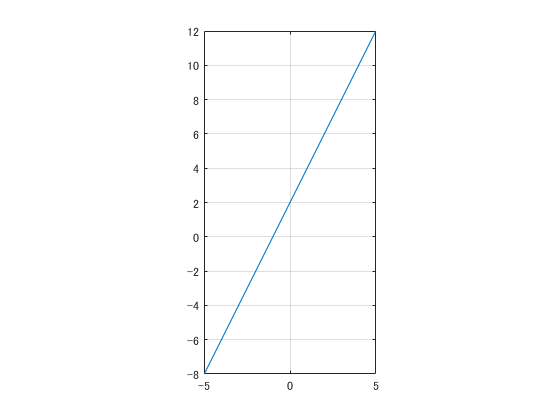


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.050657 秒。


layer = scaledActivationLayer('Name','actfcn','ScaleOut',2,'BiasOut',1,'ActivationFunction','Tanh')

layer =   scaledActivationLayer のプロパティ:

                  Name: 'actfcn'
      NumberOfChannels: 1
    ActivationFunction: 'Tanh'

   学習可能パラメーター
               ScaleIn: 1
                BiasIn: 0
              ScaleOut: 2
               BiasOut: 1

  すべてのプロパティを表示


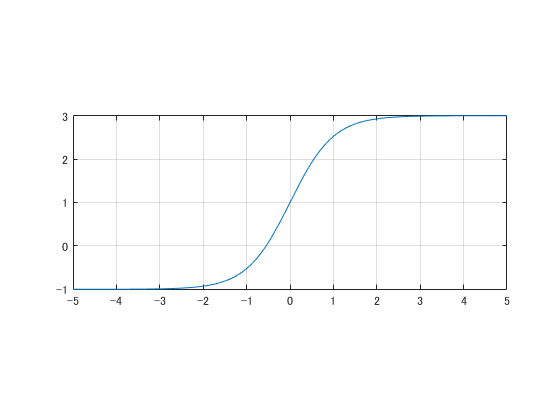


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.047016 秒。


% For max layer
dr = sqrt(2);
layer = scaledActivationLayer('Name','actfcn','BiasIn',-dr/2,'ScaleIn',1,'ScaleOut',2,'BiasOut',0,'ActivationFunction','ReLU')

layer =   scaledActivationLayer のプロパティ:

                  Name: 'actfcn'
      NumberOfChannels: 1
    ActivationFunction: 'ReLU'

   学習可能パラメーター
               ScaleIn: 1
                BiasIn: -0.7071
              ScaleOut: 2
               BiasOut: 0

  すべてのプロパティを表示


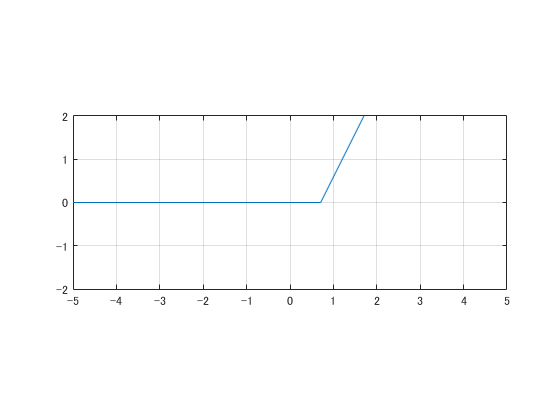


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis([-2 2 -2 2])
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.04809 秒。


% For min layer
dr = sqrt(2);
layer = scaledActivationLayer('Name','actfcn','BiasIn',-dr/2,'ScaleIn',-1,'ScaleOut',-2,'BiasOut',dr,'ActivationFunction','ReLU')

layer =   scaledActivationLayer のプロパティ:

                  Name: 'actfcn'
      NumberOfChannels: 1
    ActivationFunction: 'ReLU'

   学習可能パラメーター
               ScaleIn: -1
                BiasIn: -0.7071
              ScaleOut: -2
               BiasOut: 1.4142

  すべてのプロパティを表示


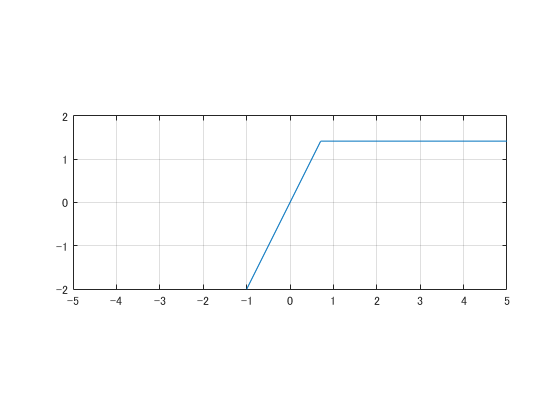


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis([-2 2 -2 2])
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.045857 秒。


% For median layer
dr = sqrt(2);
layer = scaledActivationLayer('Name','actfcn','BiasIn',0,'ScaleIn',1/dr,'ScaleOut',dr,'BiasOut',0,'ActivationFunction','ClippedReLU')

layer =   scaledActivationLayer のプロパティ:

                  Name: 'actfcn'
      NumberOfChannels: 1
    ActivationFunction: 'ClippedReLU'

   学習可能パラメーター
               ScaleIn: 0.7071
                BiasIn: 0
              ScaleOut: 1.4142
               BiasOut: 0

  すべてのプロパティを表示


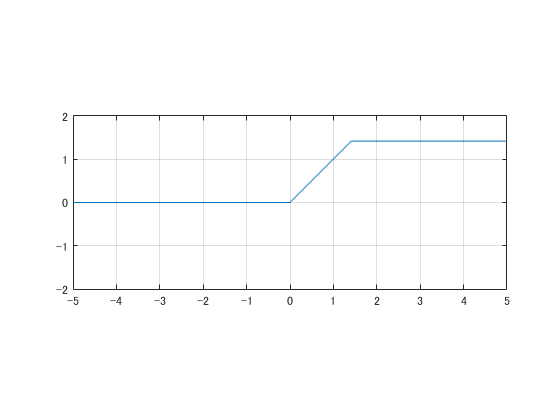


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis([-2 2 -2 2])
axis equal
grid on

checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.049782 秒。
